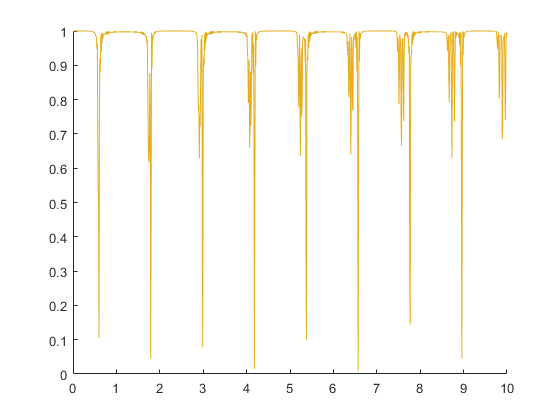

B0 = 401;%magnetic field
gama0 = 10.7083e-4;%C13 parameter
tmax = 10;
tstep = 0.01;
t = (0.01:tstep:tmax)';
Ta = 5e3;
Tb = 5e3;
%set parameter...
% wh = 1e-3*[83.8,47,55,19,33,25.1];
% th = pi/180*[21,30,54,133,132,51];
wh = 1e-3*[33,11,10,10,10];
th = pi/180*[133,20,50,89,124];

N = 56; 
%set parameter...
A = wh.*cos(th);
B = wh.*sin(th);
AB = formAB(A,B)';
AB0 = AB(1:2*length(A));
wl = 2*pi*gama0*B0;
beta = t*wl;
M = ones(length(t),1);
ep = 0.01*randn(length(t),1);
for i = 1:length(A)
    wb = sqrt((2*pi*A(i)+wl)^2+(2*pi*B(i))^2);
    mz = (2*pi*A(i)+wl)/wb;
    mx = 2*pi*B(i)/wb;
    alpha = t*wb;
    Cphi = cos(alpha).*cos(beta)-mz*sin(alpha).*sin(beta);
    phi = acos(Cphi);
    n01 = mx^2*(1-cos(alpha)).*(1-cos(beta))./(1+Cphi);
    M = M.*(1-n01.*sin(N*phi/2).^2);
end
%1-n0*n1 is n01
%plot Px
% M = 1-n01.*(sin(N*phi/2)).^2;
Px = 1/2*M+1/2;
for i = 1:length(t)
    if Px(i)>1
         Px(i) = Px(i)-2*ep(i);
    end
end
figure
hold on;
axis([0 tmax 0 1]);
plot(t,Px,'color',rand(1,3));

function AB = formAB(A0,B0)
    AB = zeros(1,20);
    for i = 1:length(A0)
        AB(2*i-1) = A0(i);
        AB(2*i) = B0(i);
    end
end
